# MZI Transfer Function 

## Introduction

Use this script to simulate the optical transmission spectrum (or transfer function) of the Mach-Zehnder Interferometer. 

## Task

Use this code to experiment with the MZI behaviour, gain insight into how the spectrum changes as a function of $L_2-L_1$, see how loss impacts the extinction ratio, and so on. Also, be sure to modify the compact waveguide model parameters to match the waveguide you have modelled and are planning on using in your design.

You will need to make adjustments to the constants in the model. Specifically, change the following:

- `lambda_min`, `lambda_max`: the wavelength range over which you want to plot.

- `lambda_step`: the wavelength step for the plot. Keep in mind that the Agilent/Keysight Technologies laser ([81600B](http://www.keysight.com/en/pd-214916-pn-81600B/tunable-laser-source-family)) has a wavelength resolution of 0.1 pm, however, we perform automated measurements typically with a 10 pm resolution.

- `lambda0`: the centre wavelength used for the waveguide model.

- `n1`, `n2`, `n3`: the waveguide compact model coefficients *(see Passive Photonic Components > Waveguide modelling - Lumerical MODE > Waveguide compact model)*.

- `alpha`: the propagation loss of the waveguide.

- `L1`, `L2`: the lengths of the two waveguides in the interferometer.

Note that all constants are in units of microns, unless noted.

## Simulation

The wavelength range of interest. (units: $\mu m$, microns)

lambda_min = 1.5;  % Units [µm, microns]
lambda_max = 1.6;

Typical minimum step for a tunable laser is 1-10 pm. (units: $\mu m$, microns)

lambda_step = 10; % wavelength step [picometers]
lambda=lambda_min:lambda_step*1e-6:lambda_max;

% Define the MZI transfer function
%  use Matlab anonymous functions

% Effective index:
% - as a Taylor expansion around the central wavelength, lambda0

Central wavelength, `lambda0`. (units: $\mu m$, microns)

lambda0 = 1.55; 

Constants from the waveguide model.

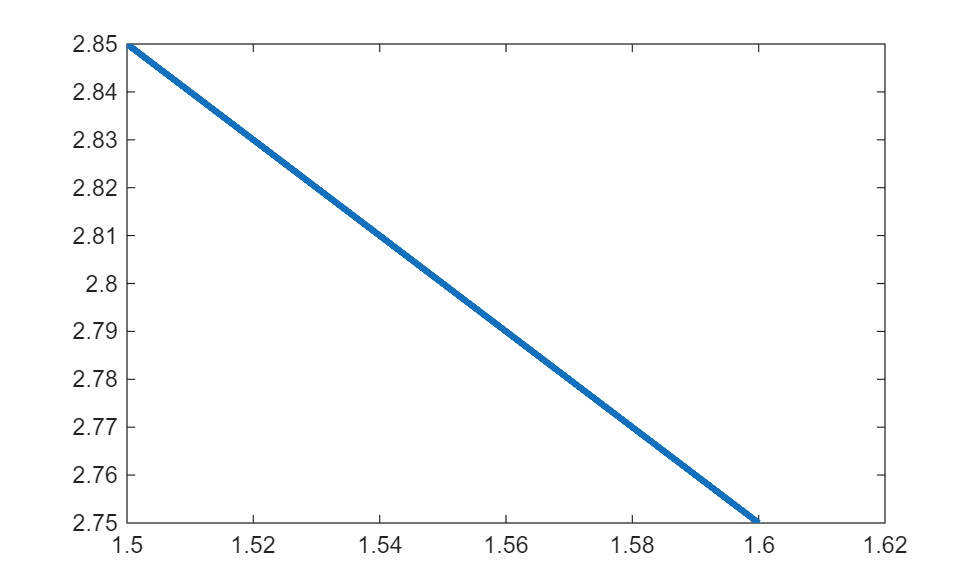

n1 = 2.8; 
n2 = -1; 
n3 = 0;  
neff = @(lambda) ...
		(n1 + n2.*(lambda-lambda0) + n3.*(lambda-lambda0).^2); 
% plot, and check if this is as expected:
figure;
plot(lambda, neff(lambda),'LineWidth',3);

Propagation loss (units: $\mu^{-1}$)

alpha = 0.001;
% Complex propagation constant for the waveguide
beta = @(lambda) ...
		(2*pi*neff(lambda)./lambda - 1i*alpha/2*ones(1,length(lambda)) );


% MZI transfer function
T_MZI = @(L1, L2, lambda) ...
        ( 0.25* abs(exp(-1i*beta(lambda)*L1)+exp(-1i*beta(lambda)*L2)).^2);

% plot, and check if this is as expected:

Waveguide lengths (units: $\mu m$, microns)

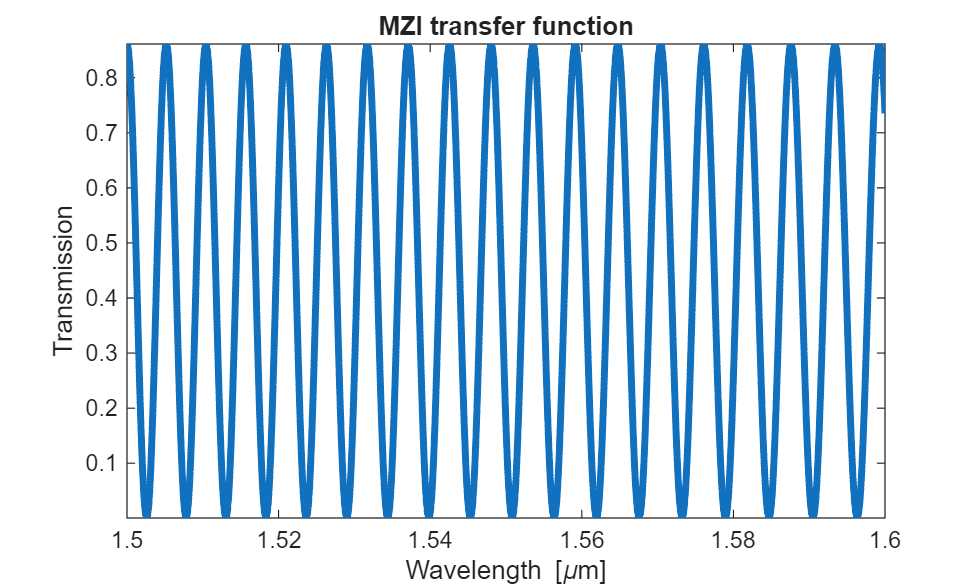

L1=100;
L2=200;  % Units [µm, microns], variable
figure;
plot(lambda, T_MZI(L1, L2, lambda),'LineWidth',3);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission');
axis tight
title ('MZI transfer function');

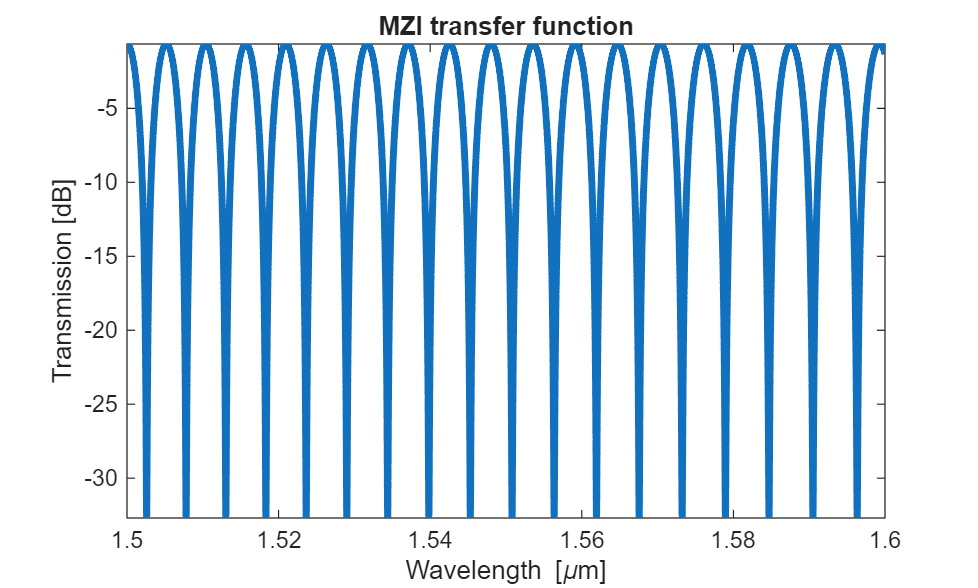


figure;
T_MZI_dB = 10*log10(T_MZI(L1, L2, lambda));
plot(lambda, T_MZI_dB,'LineWidth',3);
xlabel ('Wavelength [\mum]');
ylabel ('Transmission [dB]');
axis tight
title ('MZI transfer function');

% Phot1x_MZI_matlab.m
% by Lukas Chrostowski, 2015